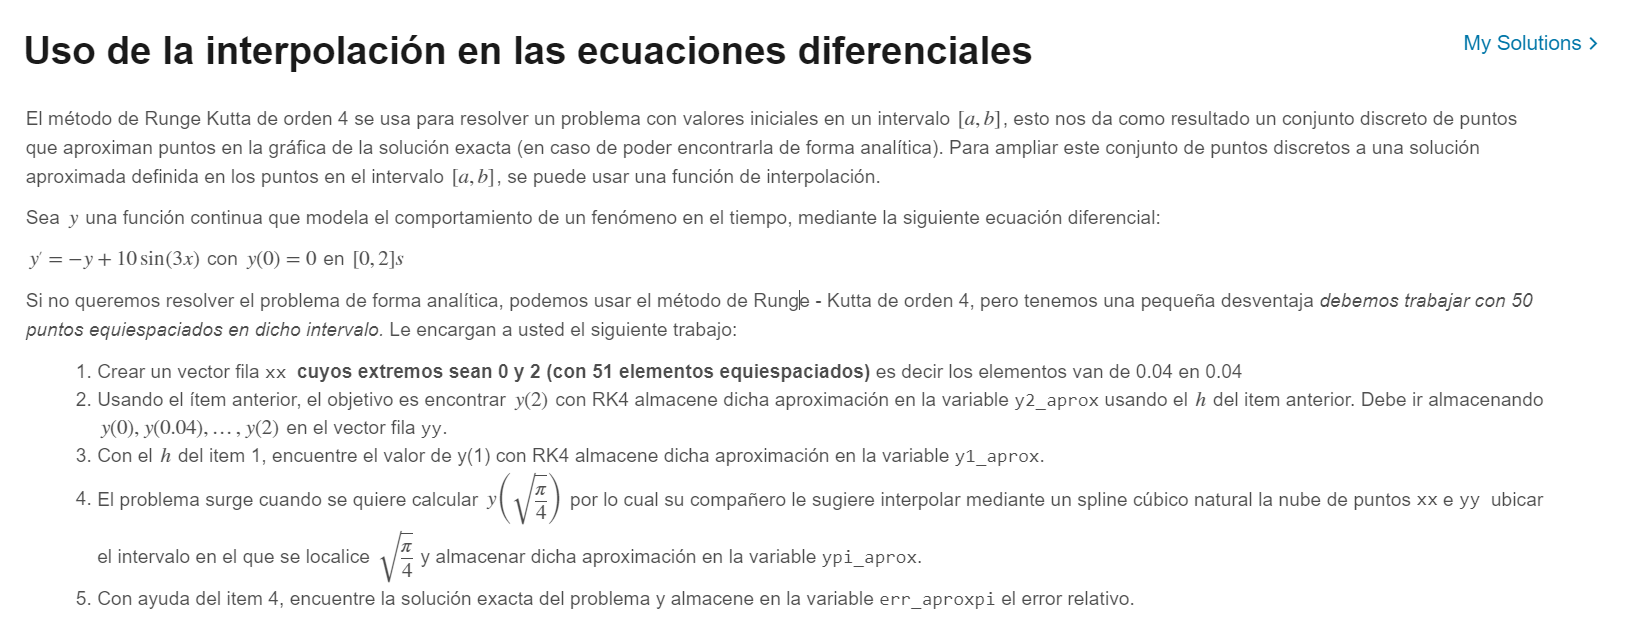

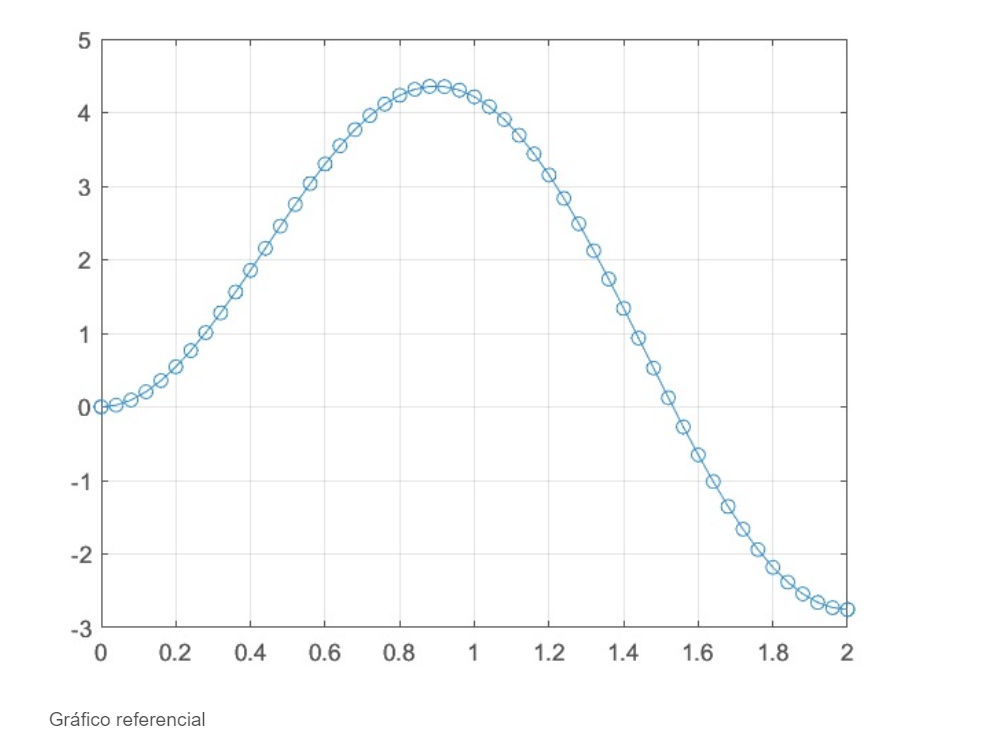

%primer item 
xx=[0:0.04:2]

xx =                    0   0.040000000000000   0.080000000000000   0.120000000000000   0.160000000000000   0.200000000000000   0.240000000000000   0.280000000000000   0.320000000000000   0.360000000000000   0.400000000000000   0.440000000000000   0.480000000000000   0.520000000000000   0.560000000000000   0.600000000000000   0.640000000000000   0.680000000000000   0.720000000000000   0.760000000000000   0.800000000000000   0.840000000000000   0.880000000000000   0.920000000000000   0.960000000000000   1.000000000000000   1.040000000000000   1.080000000000000   1.120000000000000   1.160000000000000   1.200000000000000   1.240000000000000   1.280000000000000   1.320000000000000   1.360000000000000   1.400000000000000   1.440000000000000   1.480000000000000   1.520000000000000   1.560000000000000   1.600000000000000   1.640000000000000   1.680000000000000   1.720000000000000   1.760000000000000   1.800000000000000   1.840000000000000   1.880000000000000   1.920000000000000   1.9600000000


%segundo item 
f=@(t,y)(-y+10*sin(3*t))

f = function_handle with value:
    @(t,y)(-y+10*sin(3*t))


a=0;b=2;y0=0;h=0.04;
syms y(t) t
% T(t) = dsolve(diff(T,t) == k*(T-Ta),T(0)==800)
y(t)=dsolve(diff(y,t)==(10*sin(3*t)-y),y(0)==0)

$$y(t) = 3\,{\mathrm{e}}^{-t}-\sqrt{10}\,\cos\left(3\,t+\mathrm{atan}\left(\frac{1}{3}\right)\right)$$

y_ext=matlabFunction(y(t))

y_ext = function_handle with value:
    @(t)exp(-t).*3.0-sqrt(1.0e+1).*cos(t.*3.0+atan(1.0./3.0))


[x1,yy] = rk4(f,a,b,y0,h)

x1 =                    0
   0.040000000000000
   0.080000000000000
   0.120000000000000
   0.160000000000000
   0.200000000000000
   0.240000000000000
   0.280000000000000
   0.320000000000000
   0.360000000000000


yy =                    0
   0.023654605592902
   0.093037718679890
   0.205345040281465
   0.357225733381501
   0.544827839853336
   0.763851013772249
   1.009605808395489
   1.277078659998817
   1.561001629983048



%tercer item 
y2_aprox=yy(end)

y2_aprox =   -2.753920506034760


y1_aprox=yy(26)

y1_aprox =    4.214735904293474


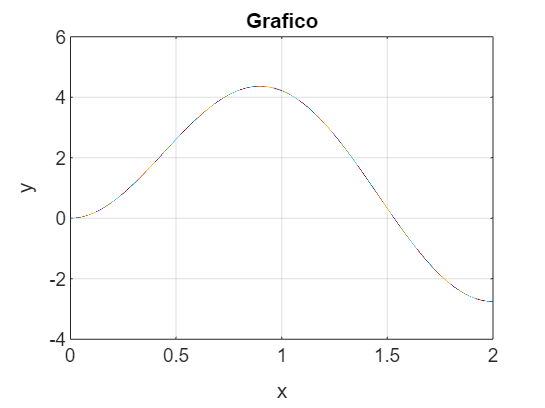

S = 1.0e+02 *

   1.528681298951398                   0   0.003467761319903                   0
  -0.498327198805891   0.183441755874168   0.010805431554870   0.000236546055929
   0.026455780725162   0.123642492017461   0.023088801470535   0.000930377186799
  -0.131064207864344   0.126817185704480   0.033107188579413   0.002053450402815
  -0.104067406558730   0.111089480760759   0.042623455238022   0.003572257333815
  -0.124595216638298   0.098601391973711   0.051011090147401   0.005448278398533
  -0.130277780442972   0.083649965977116   0.058301144465434   0.007638510137722
  -0.137662993502166   0.068016632323959   0.064367808397477   0.010096058083955
  -0.142185651670998   0.051497073103699   0.069148356614583   0.012770786599988
  -0.144972519571302   0.034434794903179   0.072585631334859   0.015610016299830




%cuarto item
%para calcular y(sqrt(pi/4))
S=splinenatural(xx,yy') % recordar que entran como fila

% se ubica en el spli 23 
s=@(x) S(23,1)*(x-xx(23-1))^3 + S(23,2)*(x-xx(23-1))^2 + S(23,3)*(x-xx(23-1)) + S(23,4)

s = function_handle with value:
    @(x)S(23,1)*(x-xx(23-1))^3+S(23,2)*(x-xx(23-1))^2+S(23,3)*(x-xx(23-1))+S(23,4)


%S(23,:)
%ESTO re
s2=@(x) S(22,1)*(x-xx(22-1))^3 + S(22,2)*(x-xx(22-1))^2 + S(22,3)*(x-xx(22-1)) + S(22,4)

s2 = function_handle with value:
    @(x)S(22,1)*(x-xx(22-1))^3+S(22,2)*(x-xx(22-1))^2+S(22,3)*(x-xx(22-1))+S(22,4)


%S(23,:)
al=sqrt(pi/4)

al =    0.886226925452758


ypi_aprox=s(al)

ypi_aprox =    4.347733963863631


ypi_aprox2=s2(al)

ypi_aprox2 =    4.347567179108943


s3=@(x) S(24,1)*(x-xx(24-1))^3 + S(24,2)*(x-xx(24-1))^2 + S(24,3)*(x-xx(24-1)) + S(24,4)

s3 = function_handle with value:
    @(x)S(24,1)*(x-xx(24-1))^3+S(24,2)*(x-xx(24-1))^2+S(24,3)*(x-xx(24-1))+S(24,4)


ypi_aprox3=s3(al)

ypi_aprox3 =    4.347734377351267


%y_rea1=interp1(xx,yy,al)% esto no se si esta bien
y_real=y_ext(al)

y_real =    4.357923937255580


err_aproxpi=abs(y_real-ypi_aprox)/abs(y_real)

err_aproxpi =    0.002338263250727


%err_aproxpi1=abs(y_rea1-ypi_aprox)/abs(y_real)


function [xx,z] = rk4(f,a,b,y0,h)
    xx = a:h:b; xx = xx';
    y1(1,1) = y0;
    for i=1:length(xx)-1
    k1 = f(xx(i),y0);
    k2 = f(xx(i) + h/2,y0 + k1*(h/2));
    k3 = f(xx(i) + h/2,y0 + k2*(h/2));
    k4 = f(xx(i)+ h,y0 + k3*h);
    y1(i+1,1) = y0 + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
    y0 = y1(i+1,1);
    end
    z = y1;
end

function S=splinenatural(X,Y)
N=length(X)-1; H=diff(X); E=diff(Y)./H;
diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
g0=0; gn=0;
A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
b=6*diff(E'); g=A\b;
g=[g0 g' gn];
for i=1:N
S(i,1)=(g(i+1)-g(i))/(6*H(i));
S(i,2)=g(i)/2;
S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
S(i,4)=Y(i);
xx=linspace(X(i),X(i+1),100);
yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
plot(xx,yy)
title('Grafico');
xlabel('x');
ylabel('y'); hold on
end
grid on, hold off
end